Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 3 -- Distribution of Dice Outcomes

%% ME 5714 -- Assignment 3
%{
    This live script will be used to complete the assigned work for ME 5714
    assignment 3. This assignment requires analyzing the data for summing
    N number of  dice in K specific amount of rolls. This will have a
    histogram for each number and roll amount. A q-q plot will be used to
    calculate the regression coefficient.
    
    Sam Kramer
    24st Jan, 2023
%}

% --Setup
    clear; clc; format compact; close all;

###     Problem Statement:

    Create a program to calculate the sum of multiple dice. Use the program to build a histogram for summing 3 die, 6 die and 10 die. The number of sums for each should be 100, 1000 and 10,000 sums. Compare the data obtained in question 1 to the normal dist. This can be done by using a q-q plot and calculating the regression coefficient.

## Problem Setup

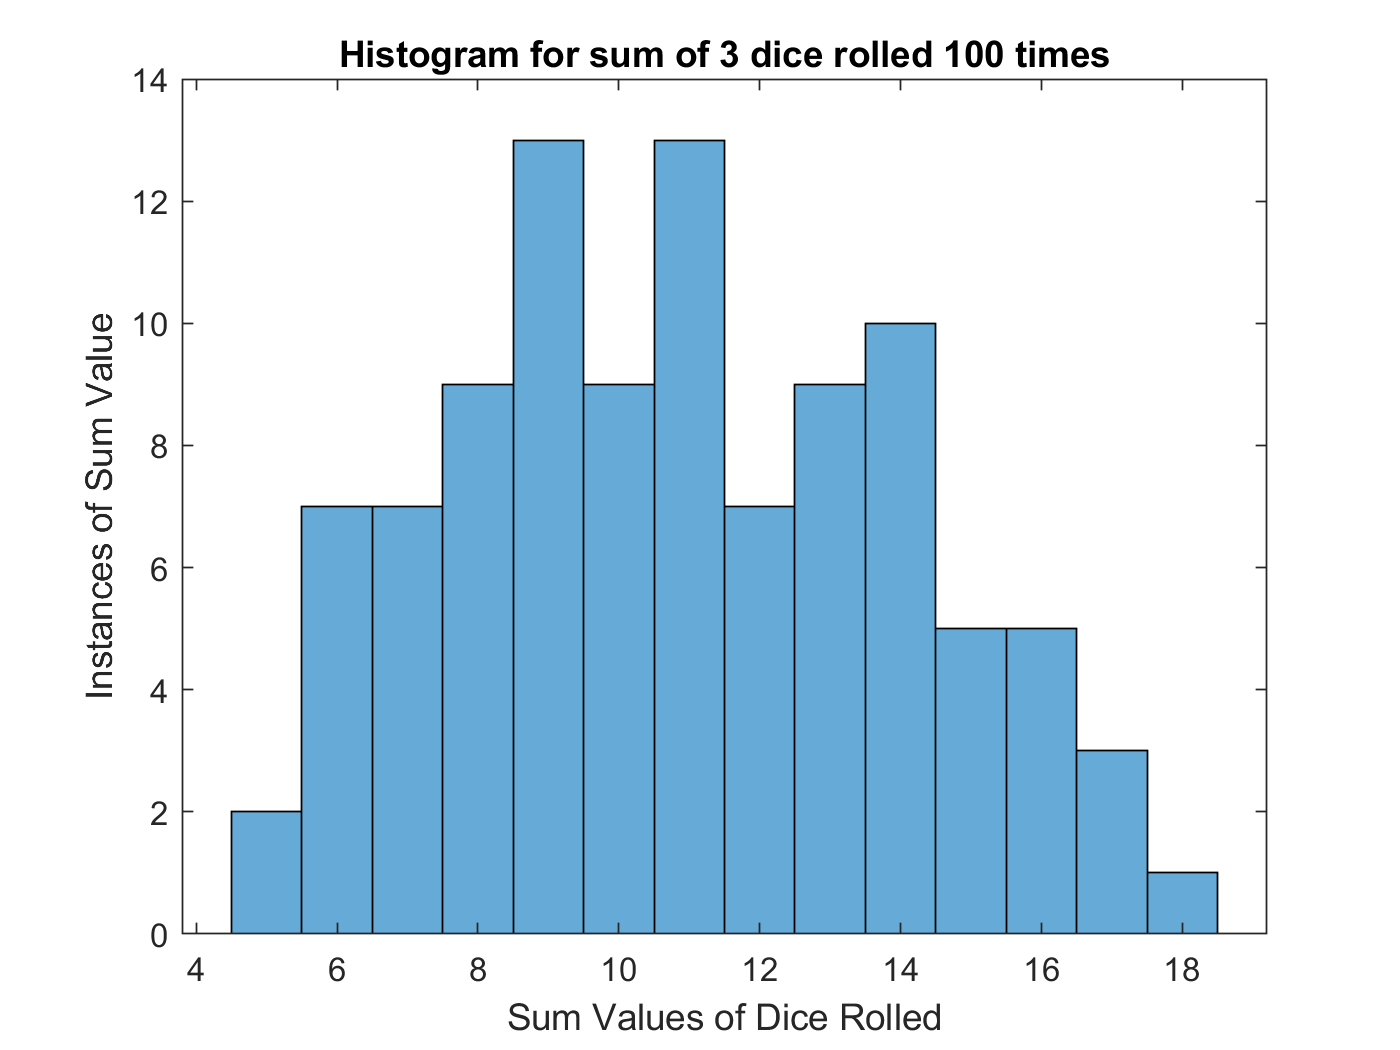

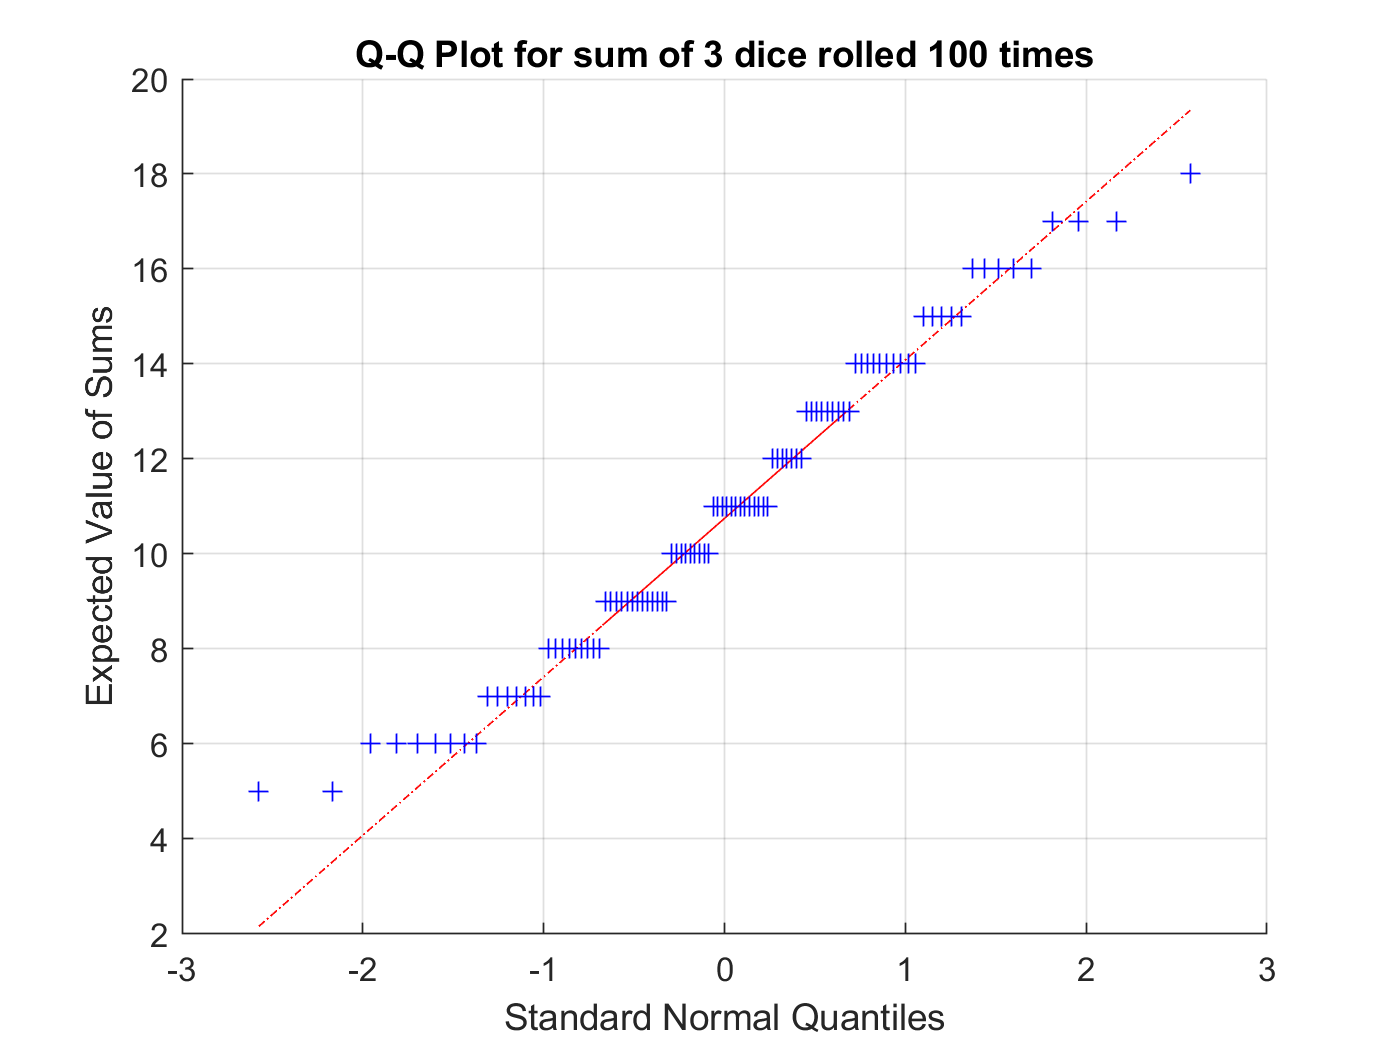

Linear Regression Coefficient is calculated to be 0.627 


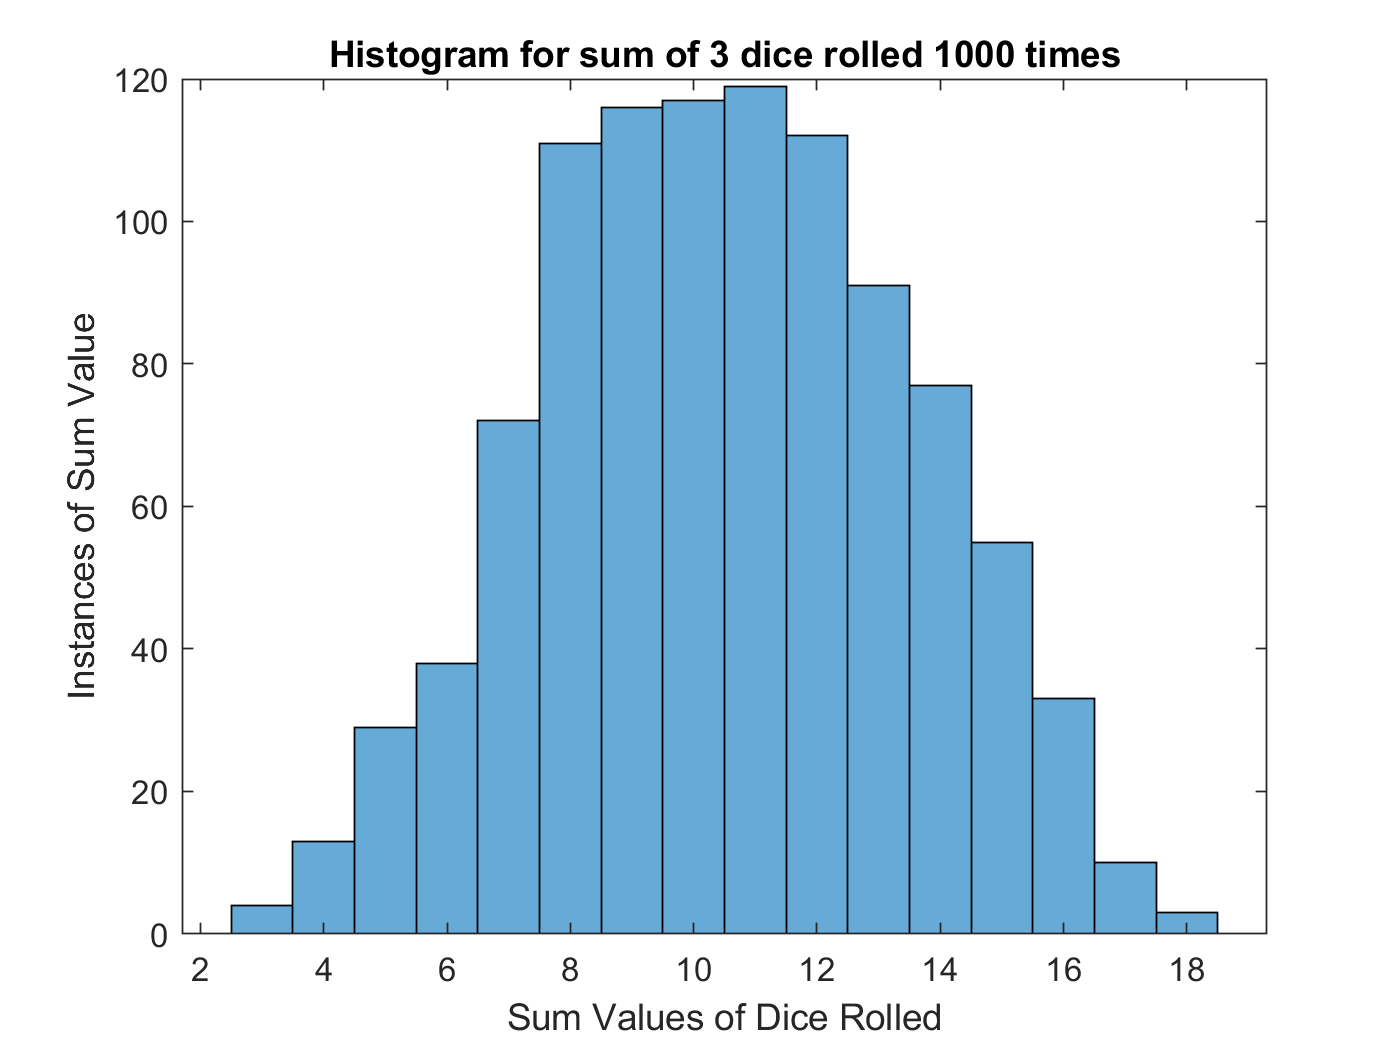

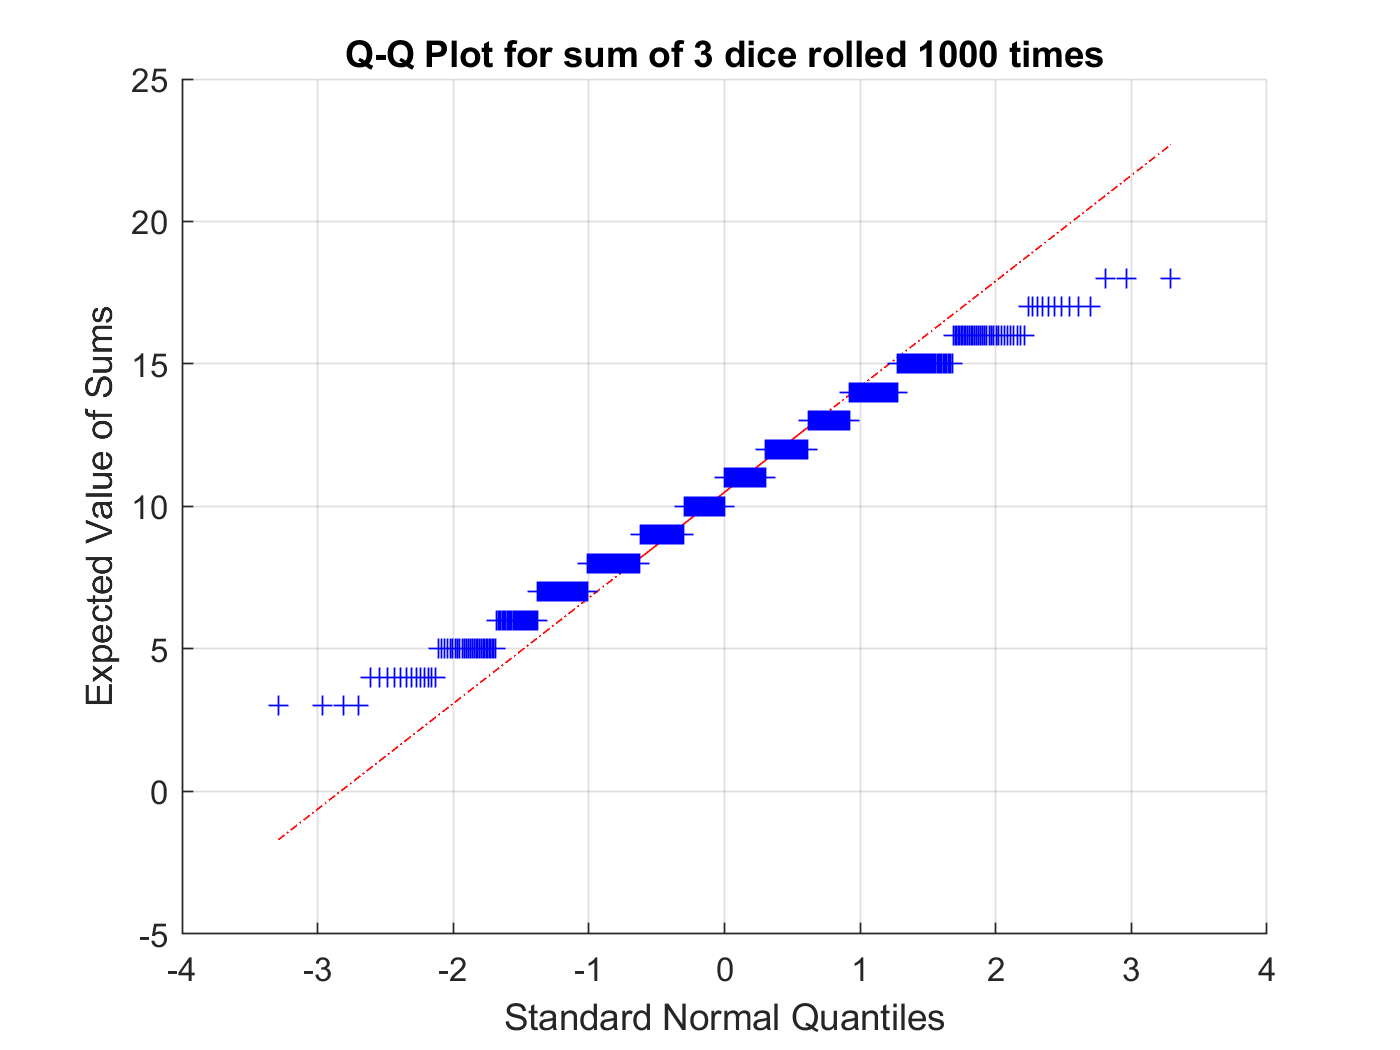

Linear Regression Coefficient is calculated to be 0.589 


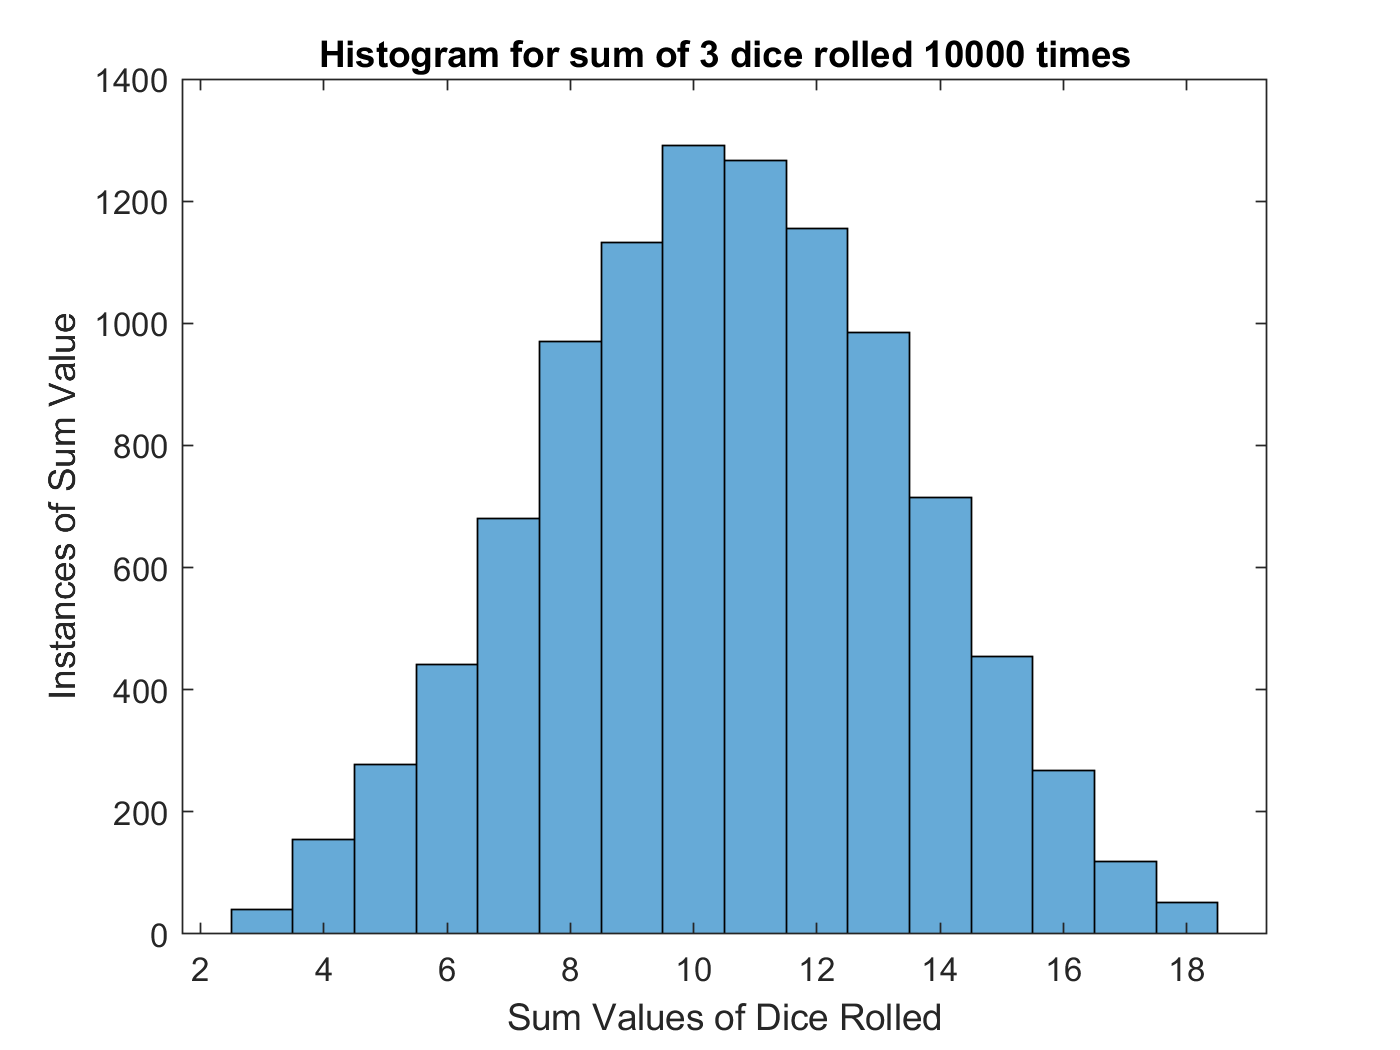

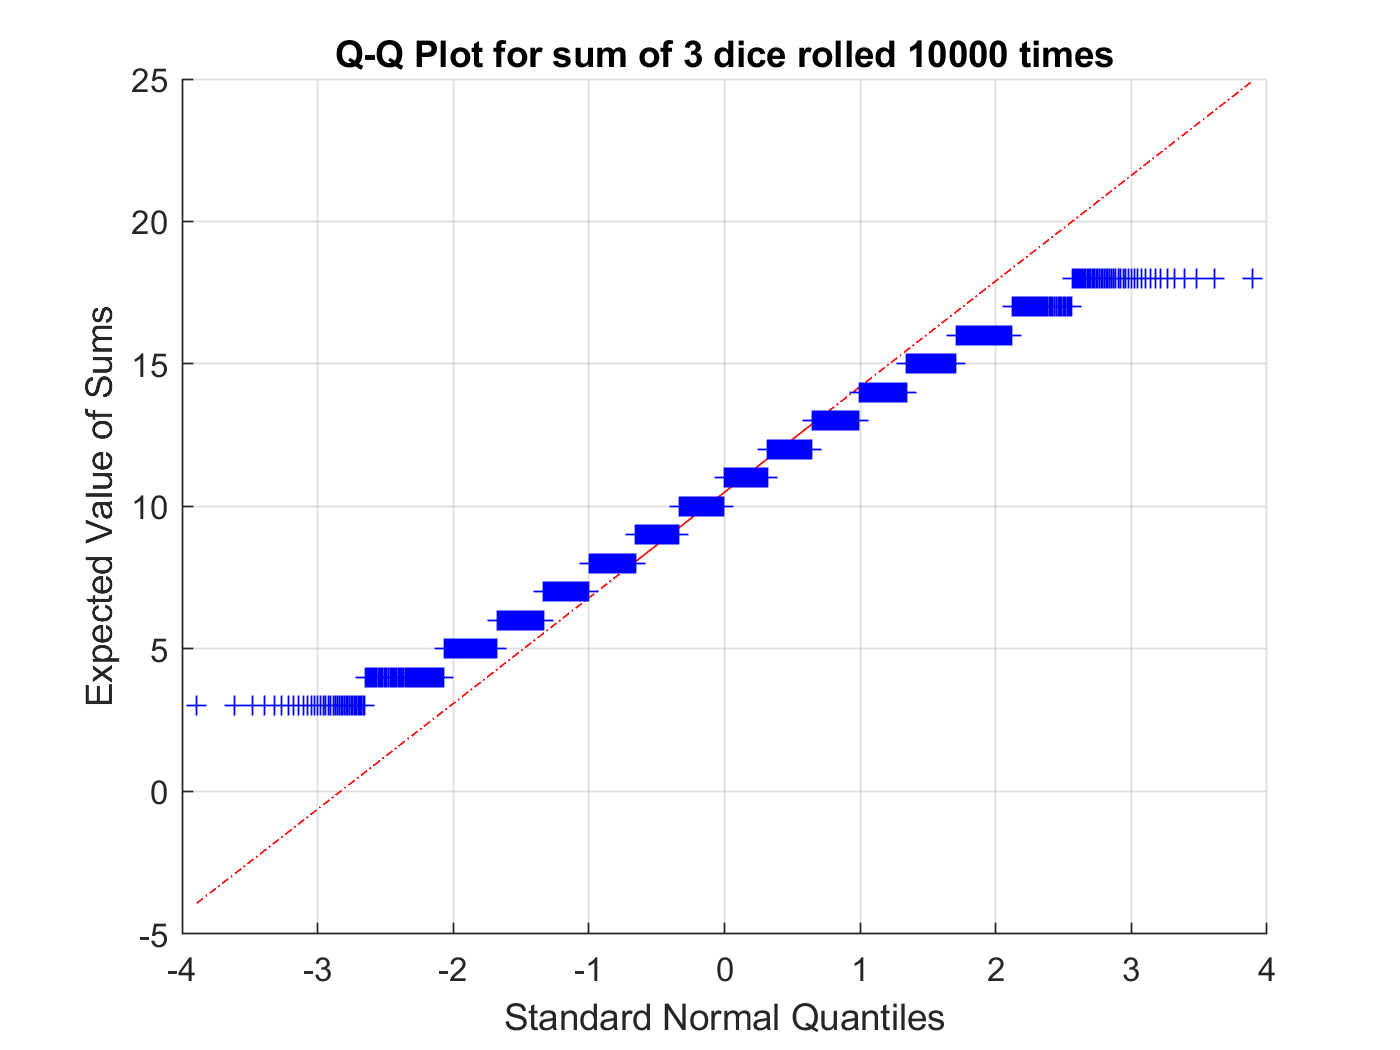

Linear Regression Coefficient is calculated to be 0.584 


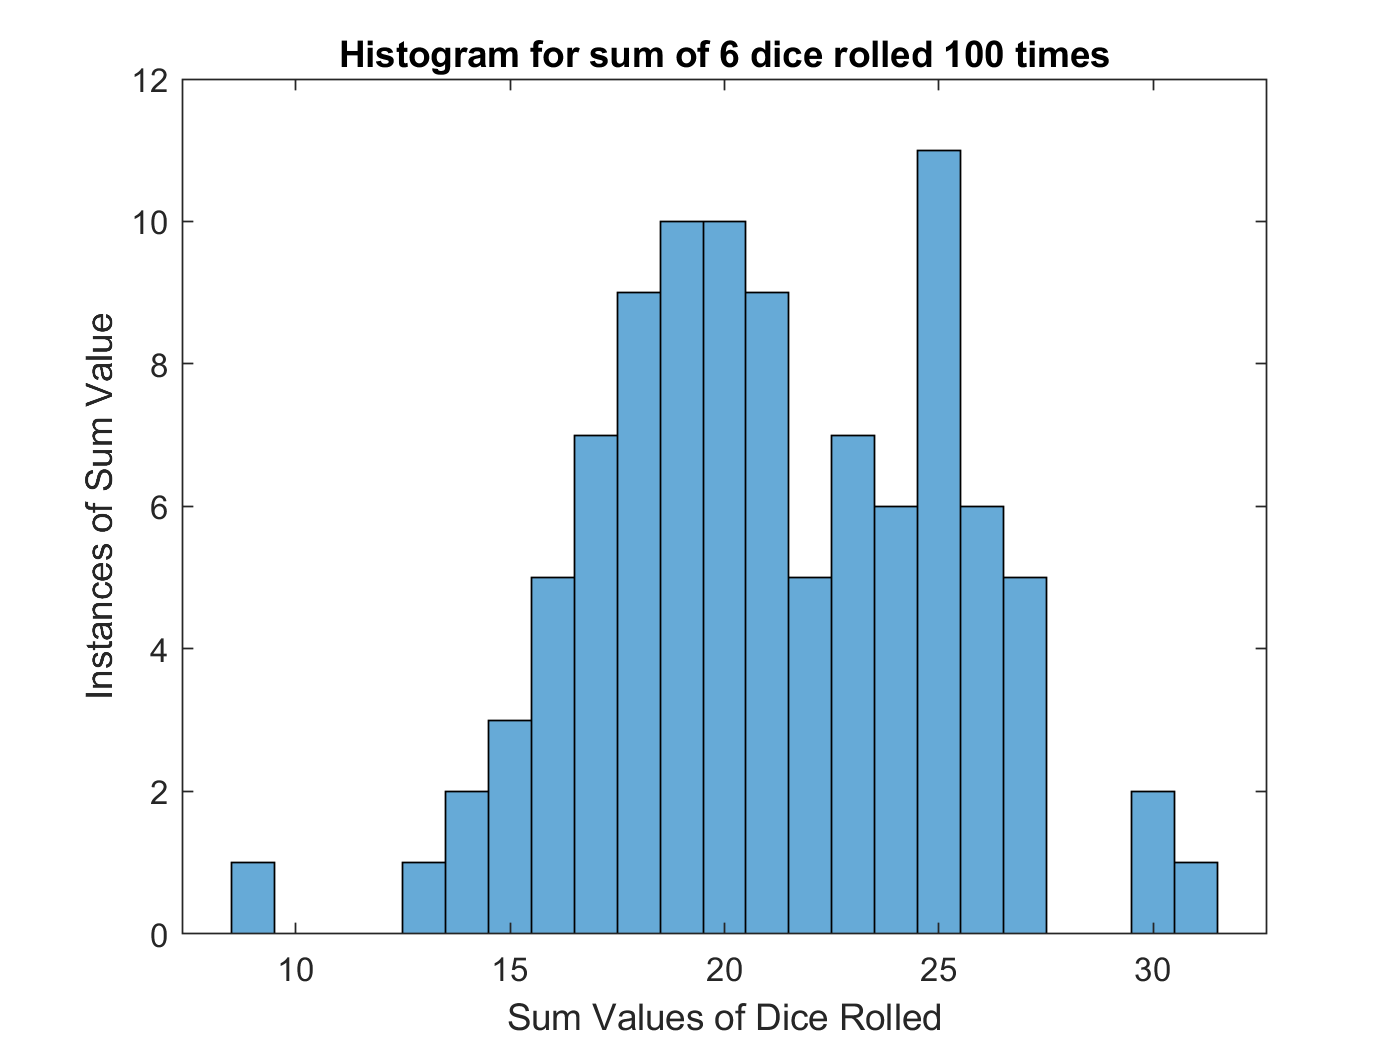

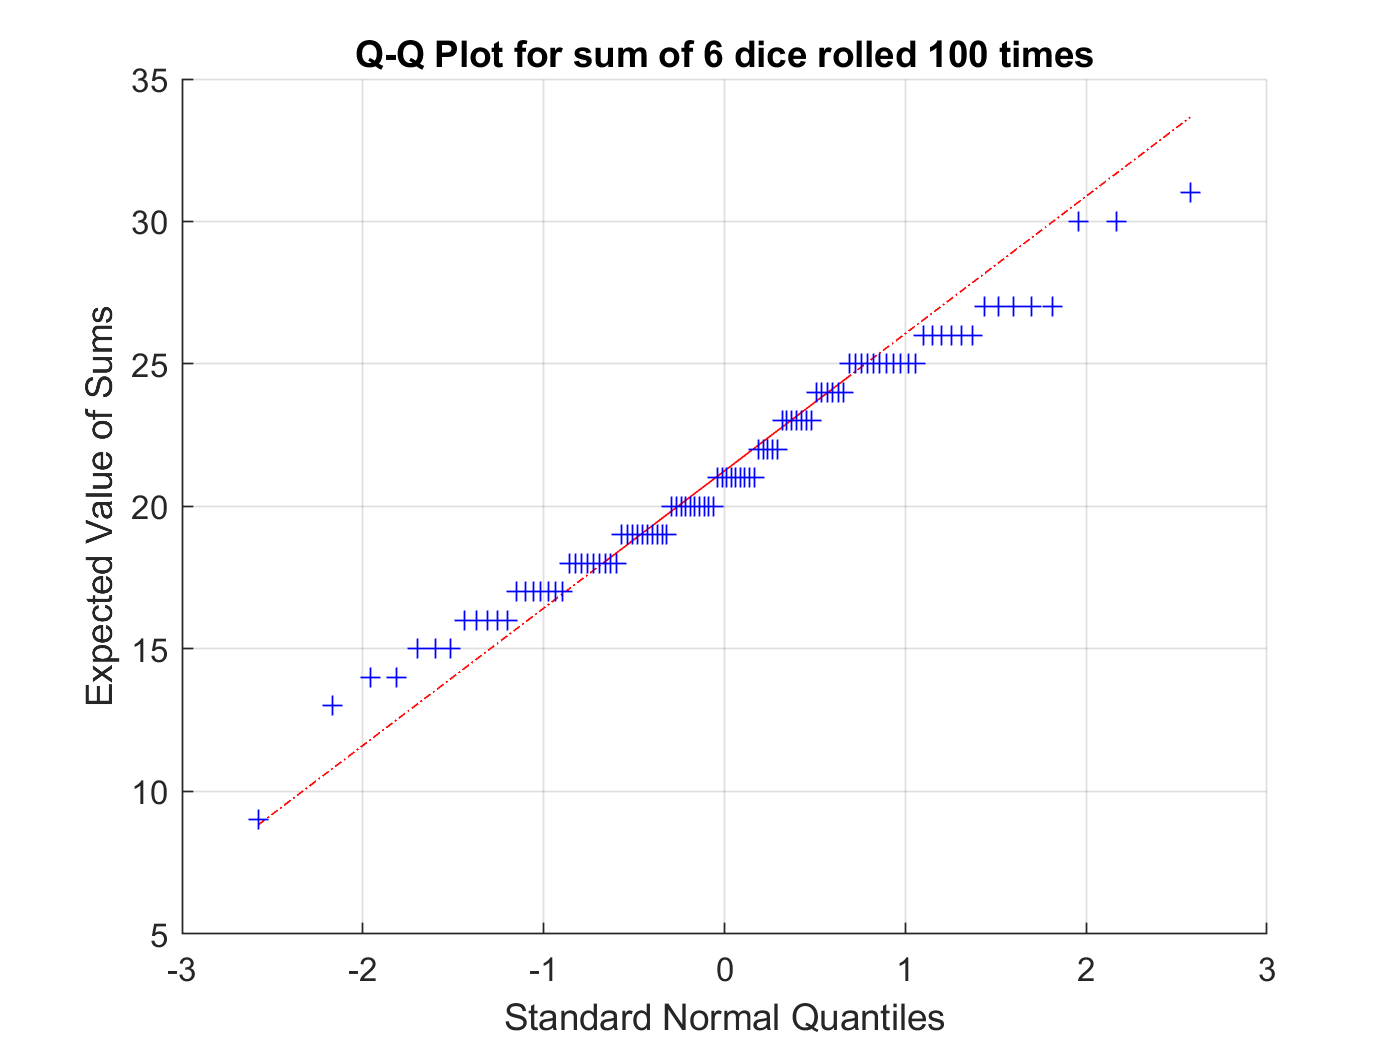

Linear Regression Coefficient is calculated to be 0.808 


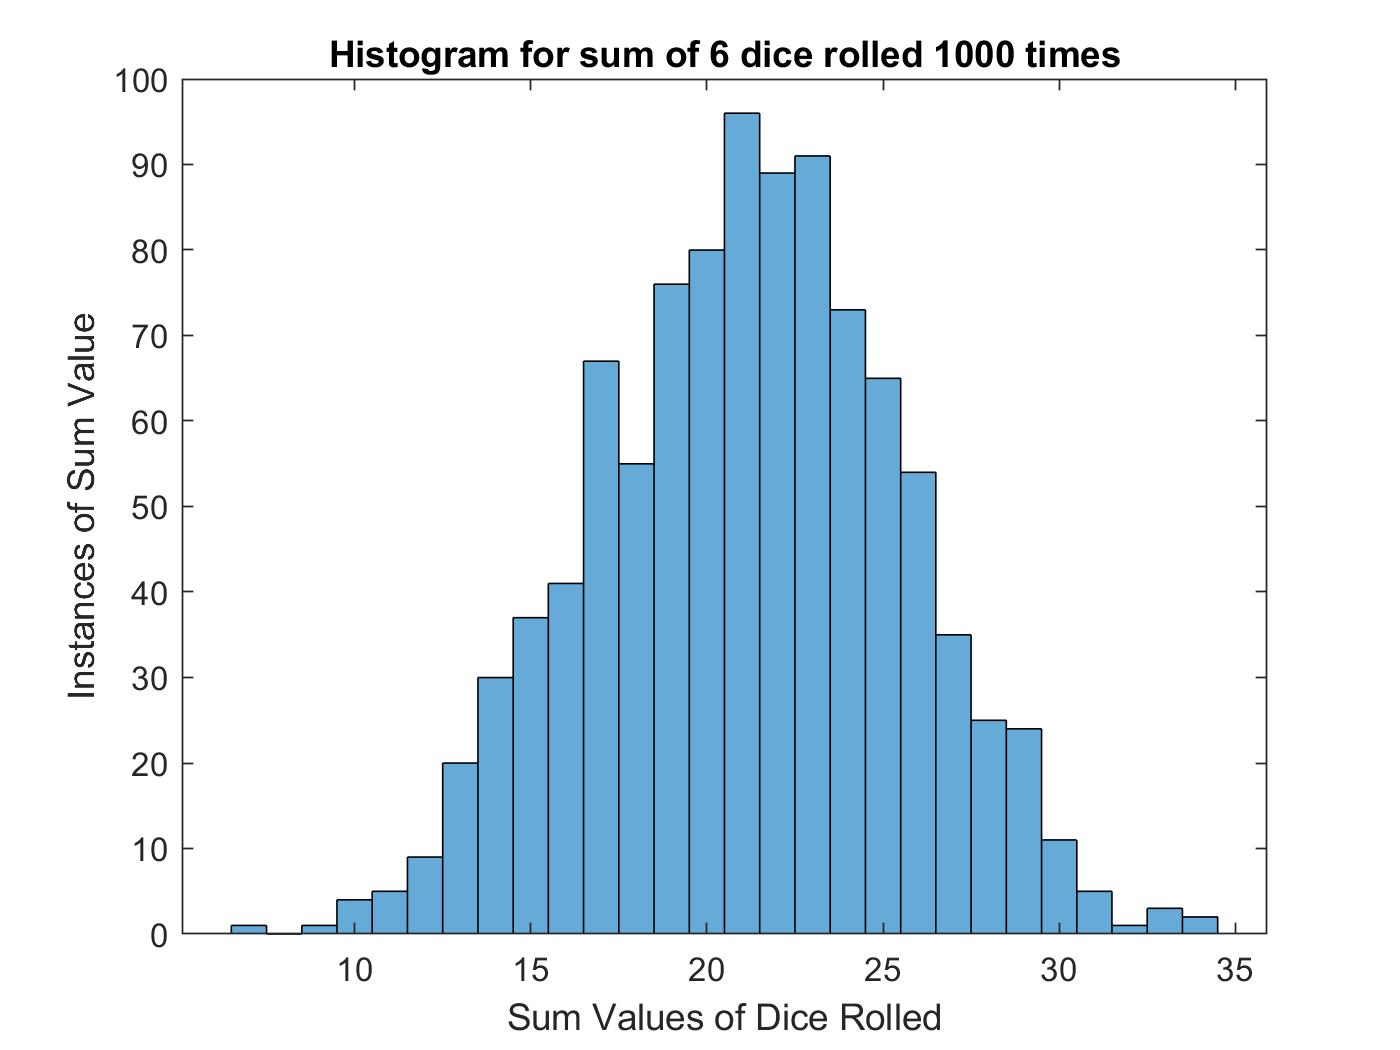

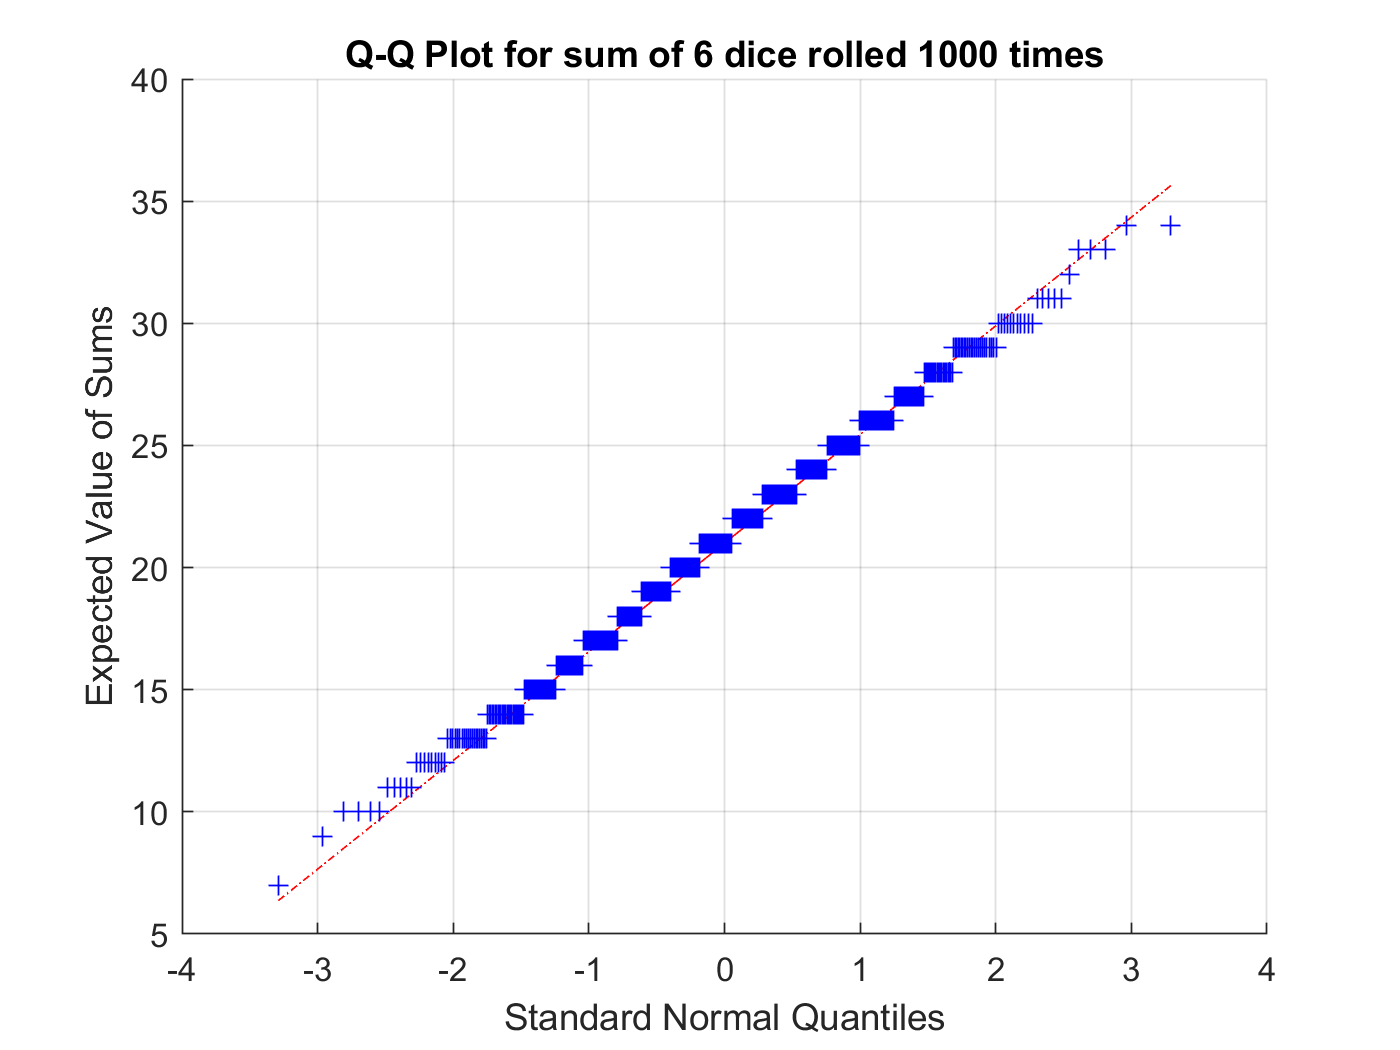

Linear Regression Coefficient is calculated to be 0.867 


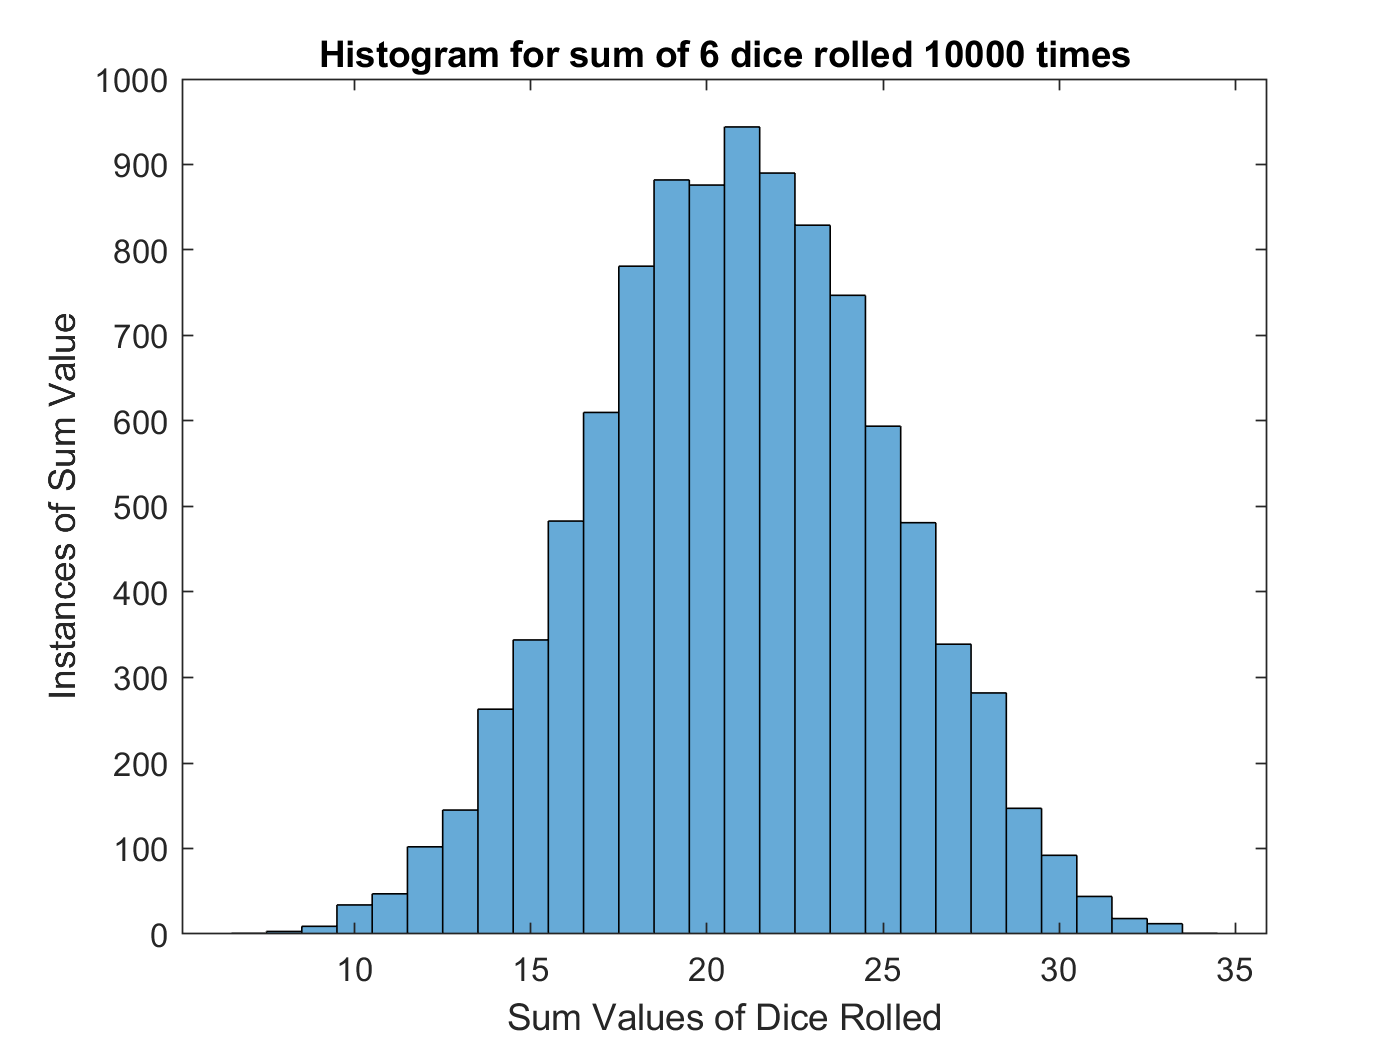

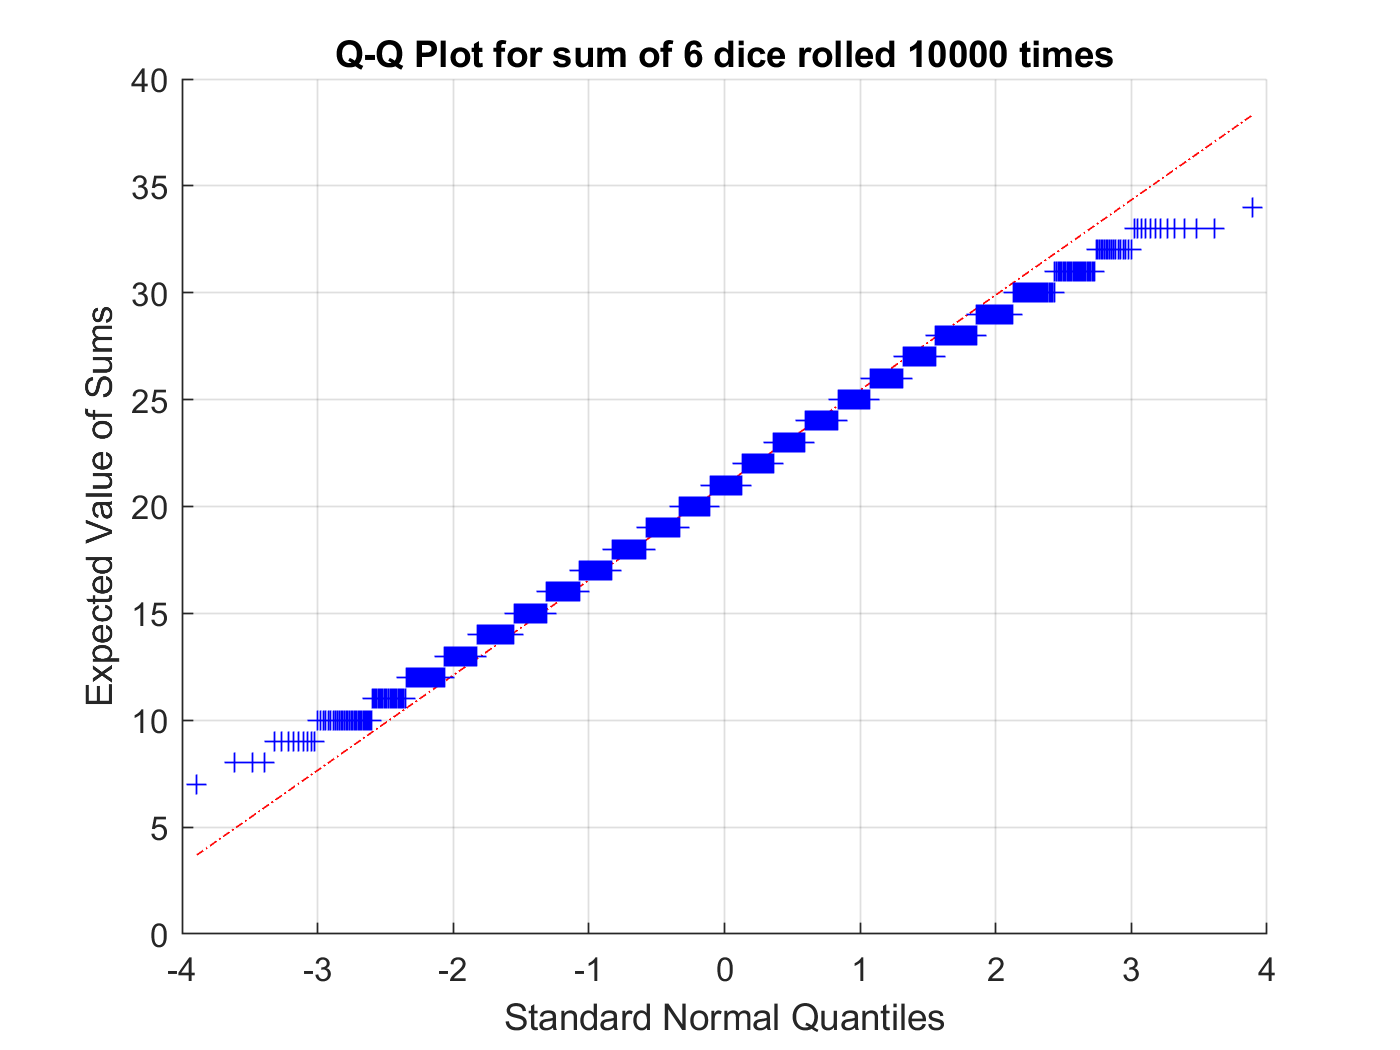

Linear Regression Coefficient is calculated to be 0.824 


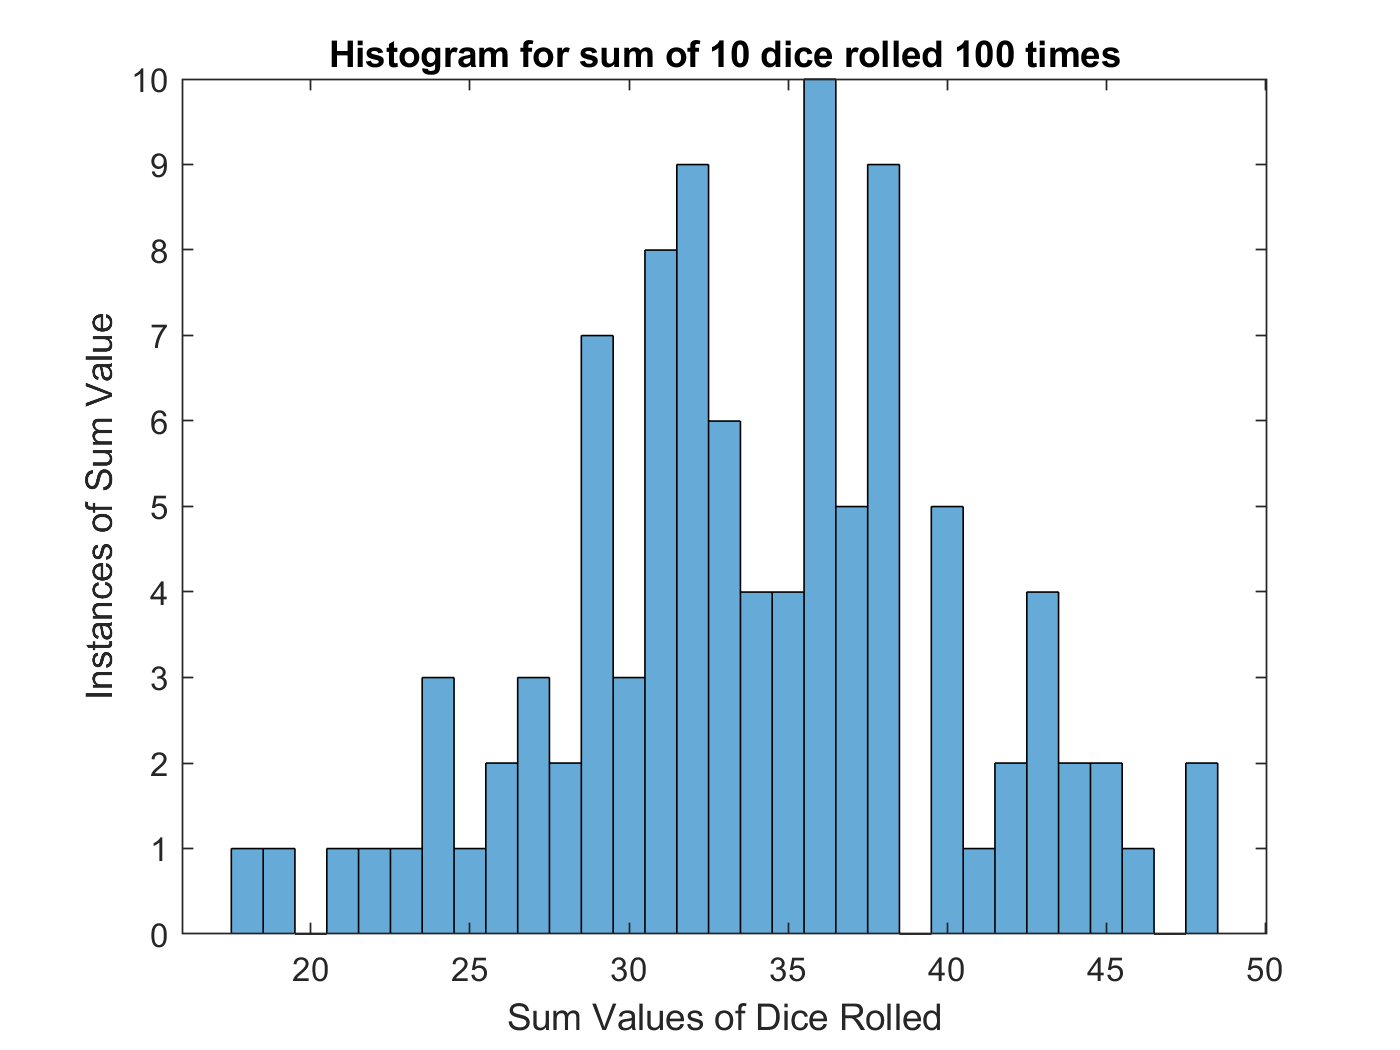

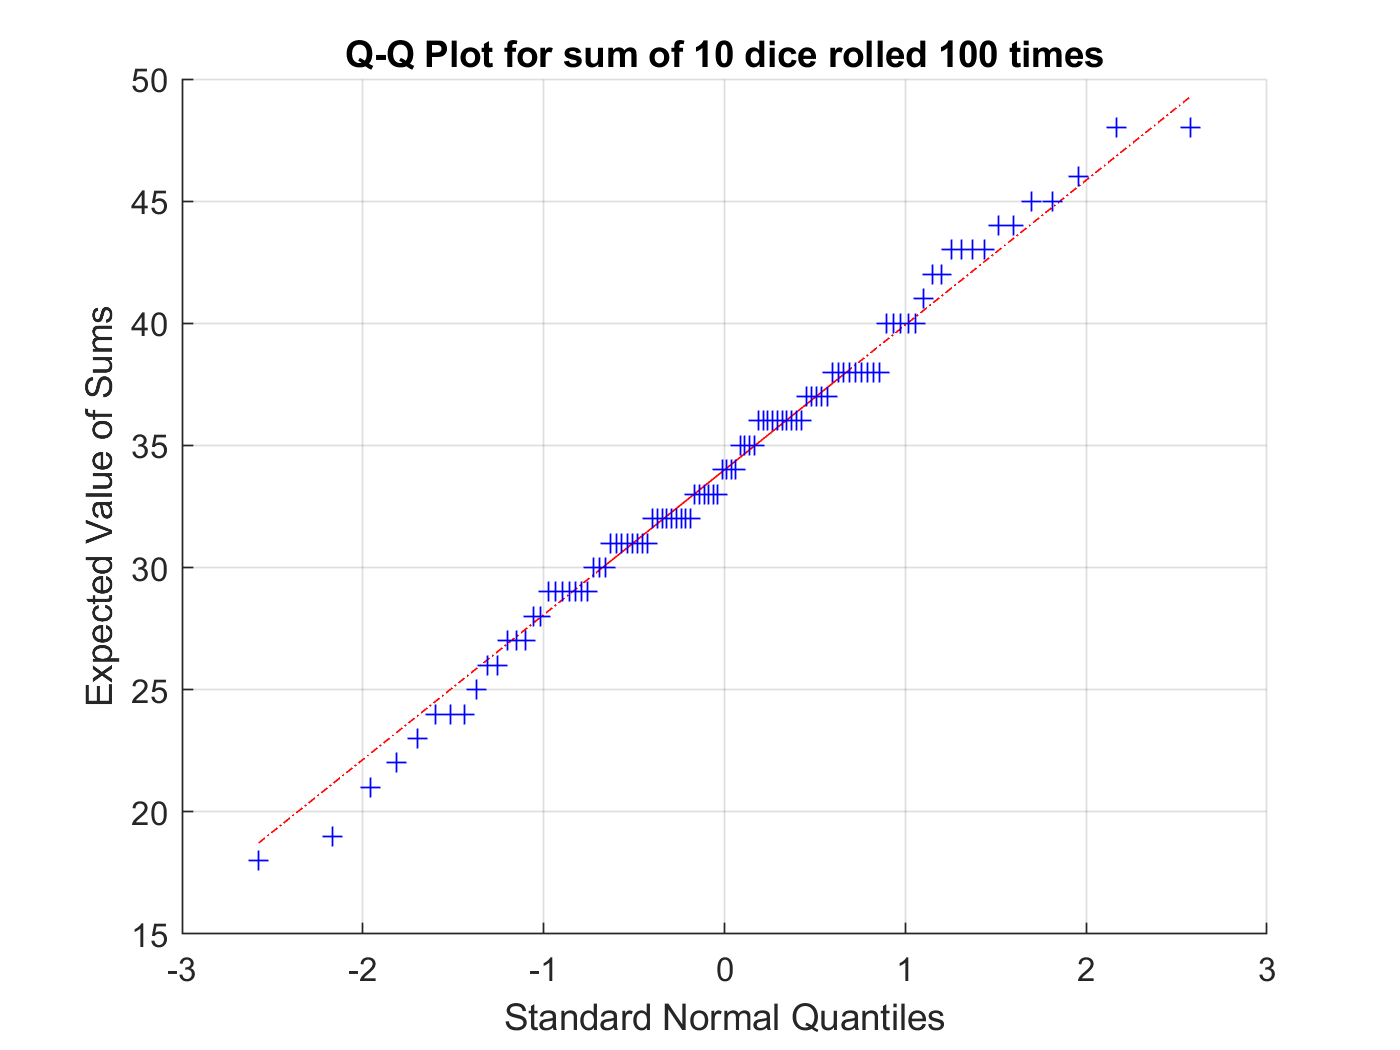

Linear Regression Coefficient is calculated to be 0.753 


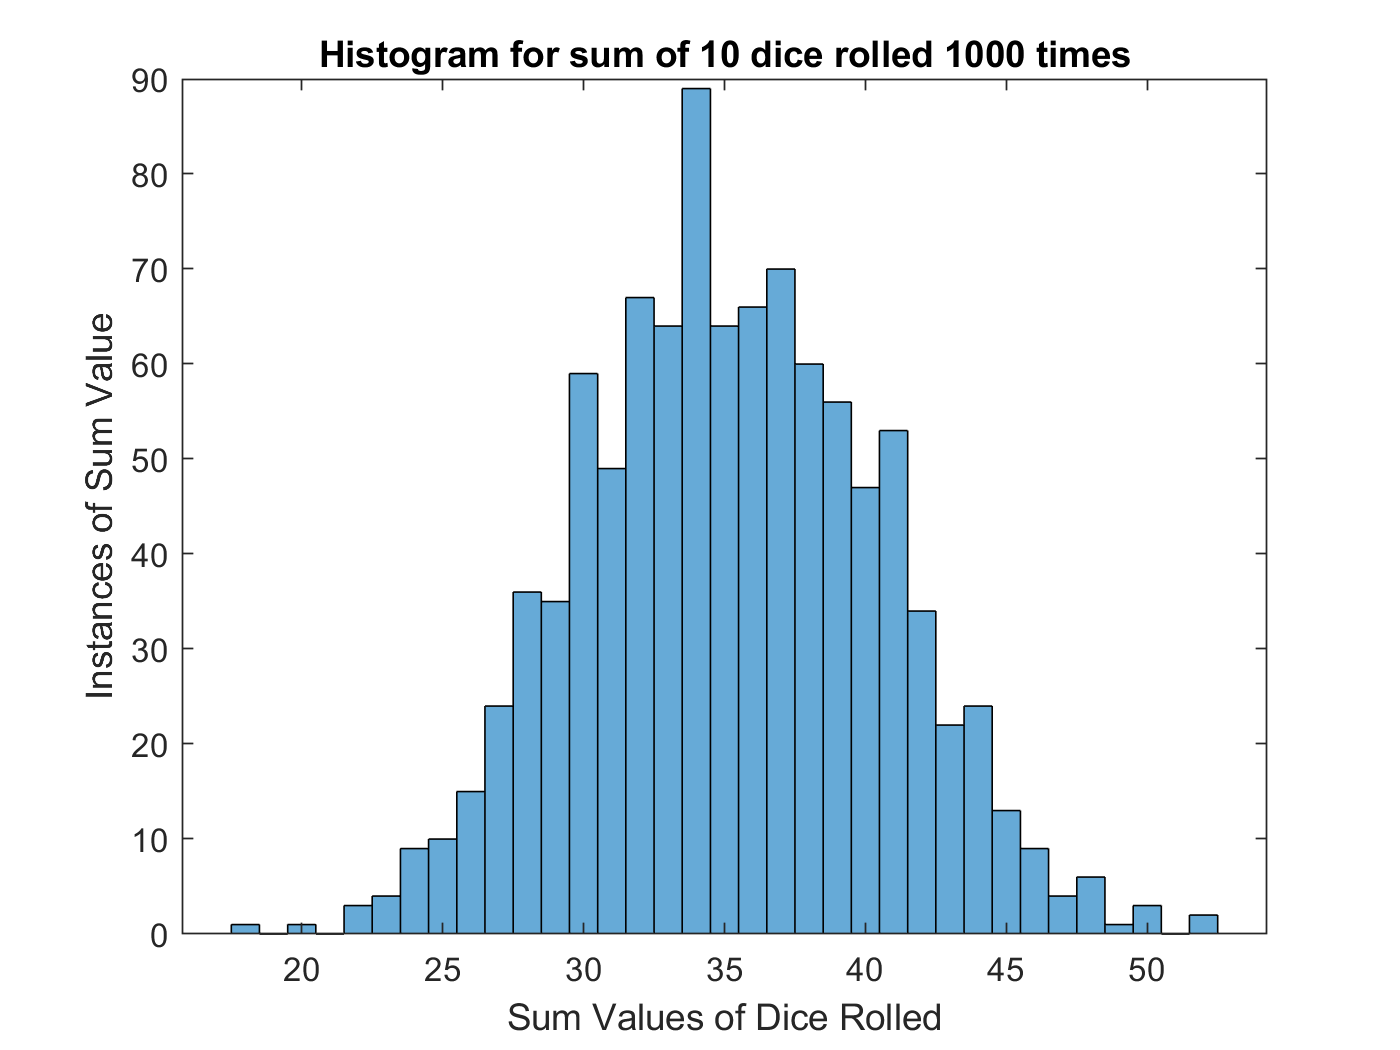

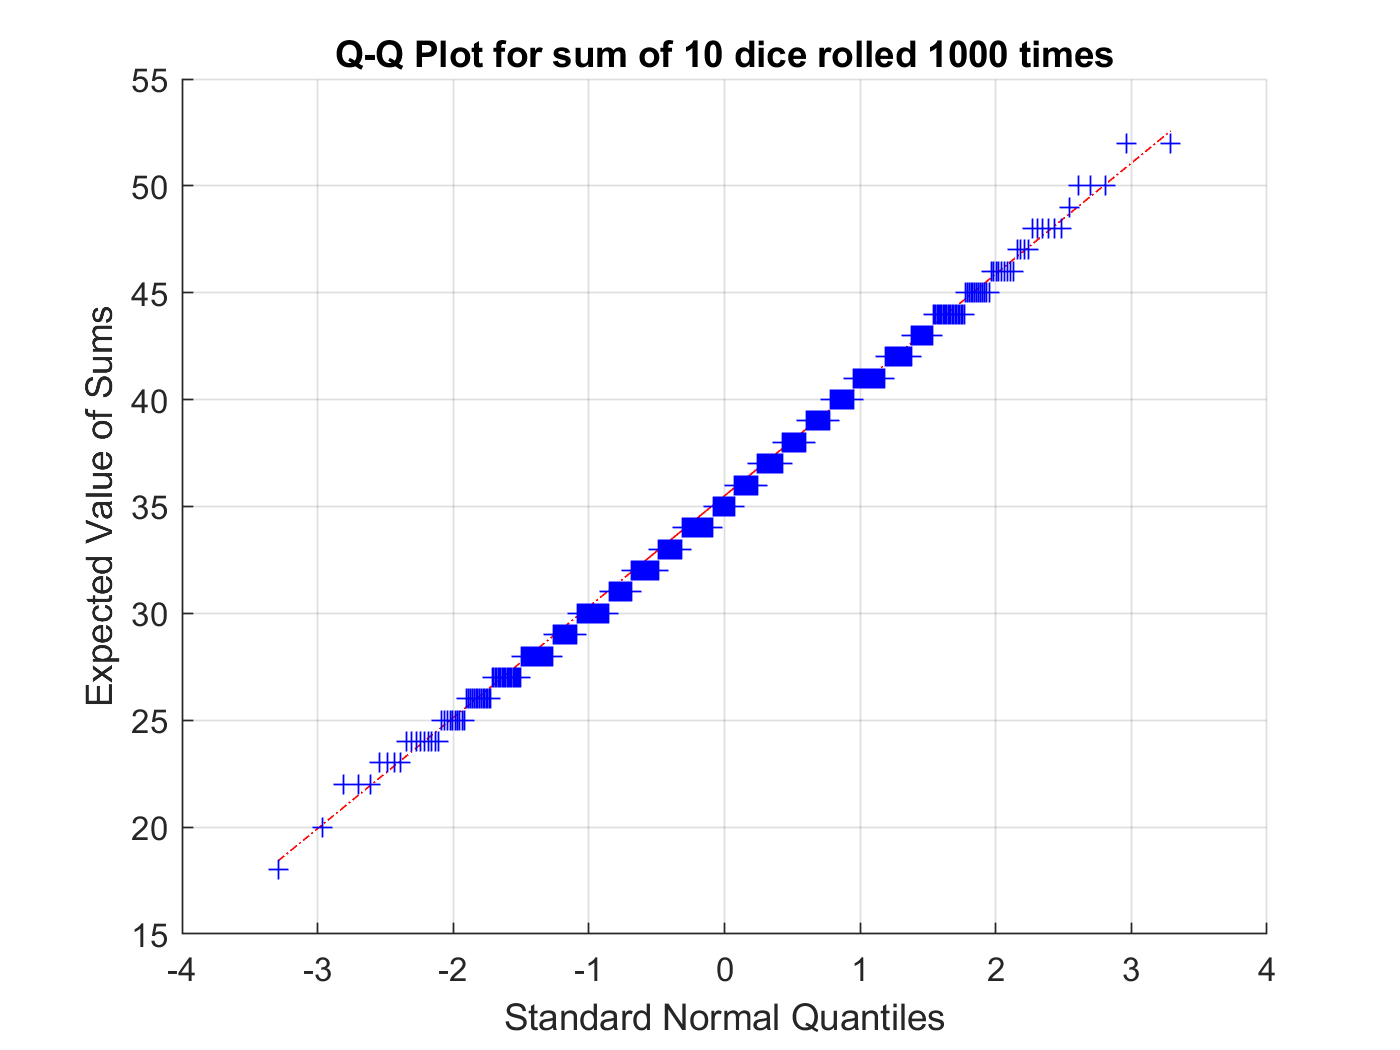

Linear Regression Coefficient is calculated to be 0.945 


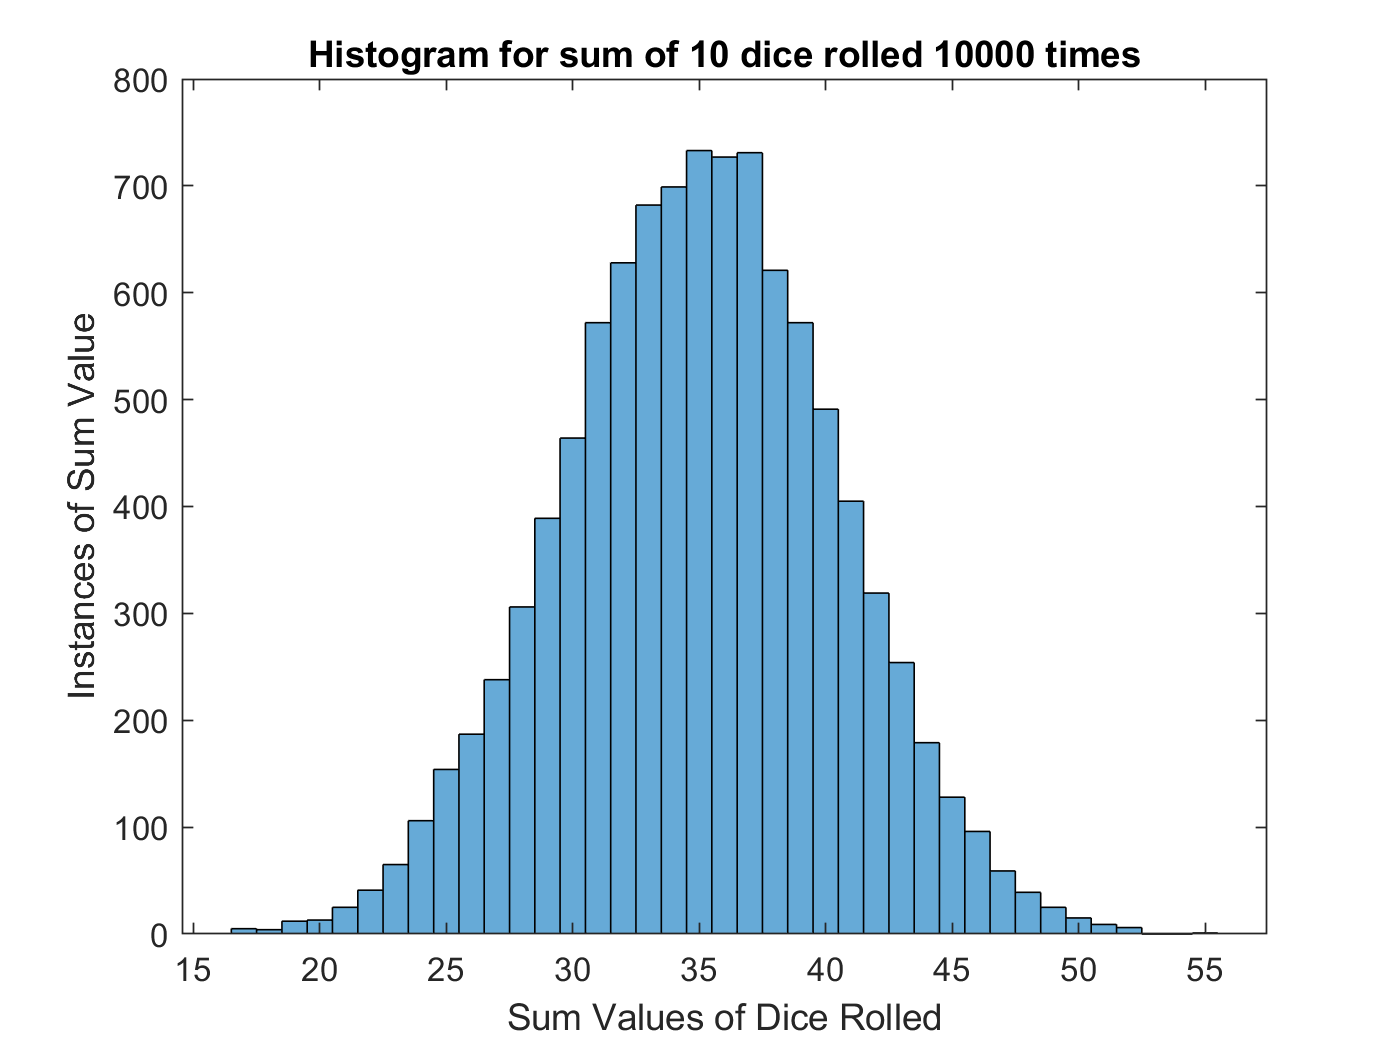

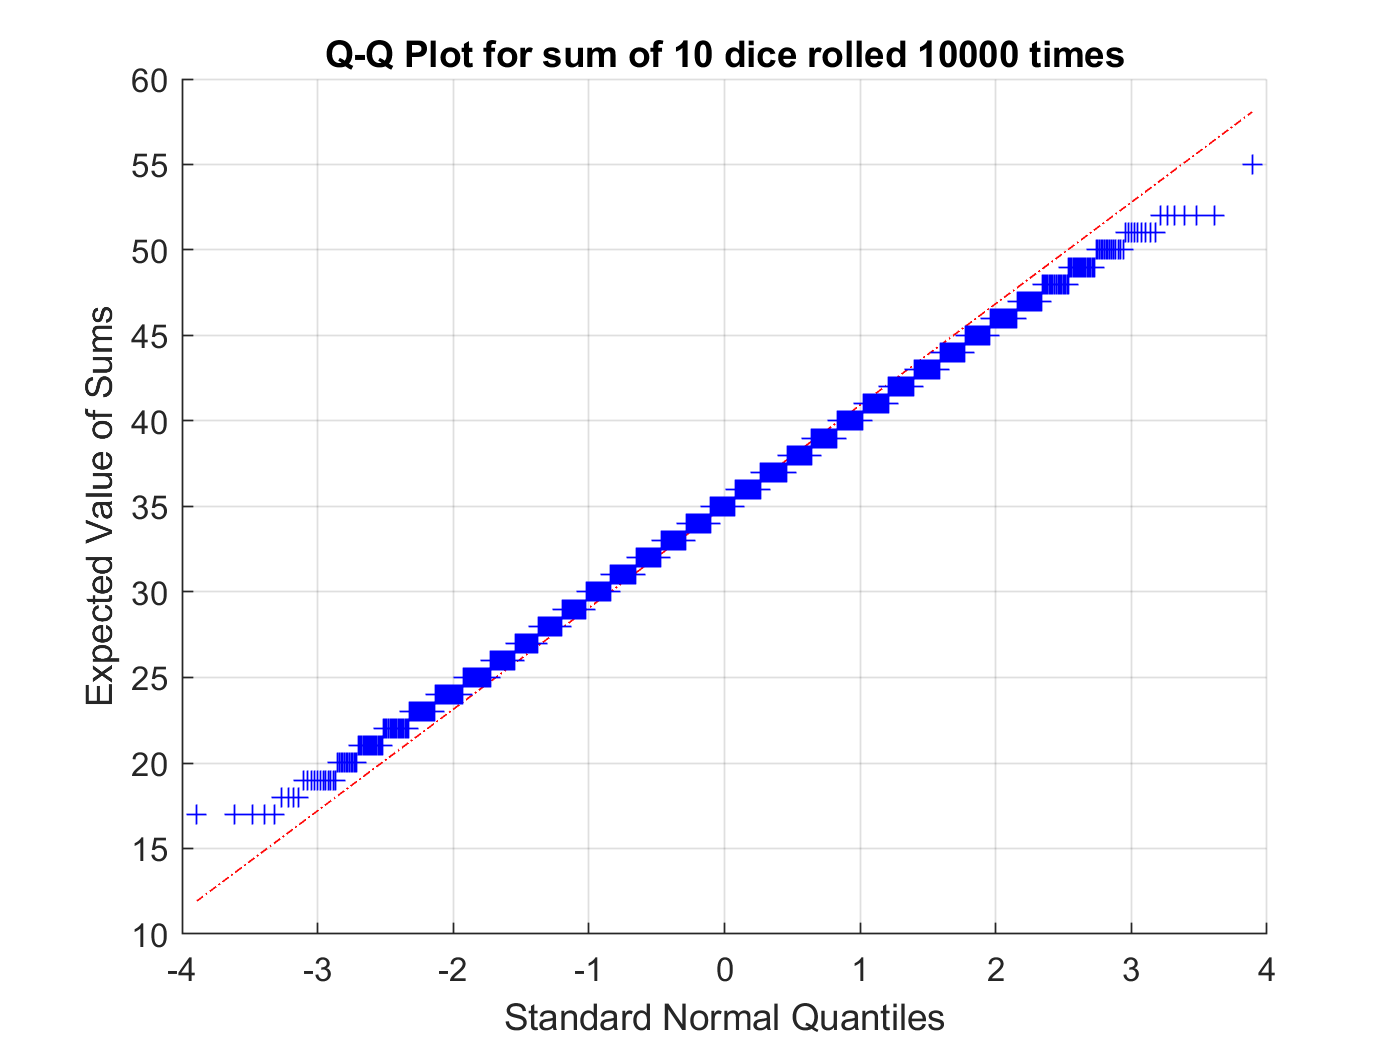

Linear Regression Coefficient is calculated to be 0.922 


% --Parameters
    number_dice = [3 6 10];             % Number of dice rolled
    number_rolls = [100 1000 10000];    % Number of times rolls
    dice = 1;                           % Initialize Dice ticker
    
% --For loop with functions
    for i = 1:length(number_dice)
        %{
            This loop goes through all 3 amount of dice being rolled and will 
            calculate 3 histograms. Outputs a total of 9 histograms.
        %}
        
        for N = 1:length(number_dice)
            %{
                Will output 3 histograms for N dice rolled 100, 1000 and
                10,000 times.
            %}
        
            % --Roll dice and sum N times
            RollNTimes(N,dice)
        
        end
        
        % --Increment the amount of dice being rolled.
        dice = dice + 1;
    
    end  

## Function Definitions

    This section will be on the function definitions that will be used in order to calculate the required histograms for the homework. There are two helper functions that are used to calculate the histograms.

function sum = RollDice(Number_Dice)
%{
    This function will be used to calculate the single roll of N amount of
    dice that are being rolled simultaneously.
%}
    
% --Initialize function parameters
    sum = 0;                            % Initialize the sum to zero
    number_dice = [3 6 10];             % Number of dice rolled
    
% --For loop to sum all dice being rolled simultaneously.
    for j = 1:number_dice(Number_Dice)
        %{
            Loops through amount of dice being rolled times and adds 
            that specific instance to the sum value. This calculates the
            sum of all the dice being rolled at once.
        %}
        
        % --Sum all rolls
            x = randi([1 6]);                       % Generates roll
            sum = sum + x;                          % Sums all rolls
    end
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function RollNTimes(N,dice)
%{
    This will be the function that will be used to calculate the sums of
    dice sets that are rolled N times. So if you want to roll N dice N
    times it will output histograms showing the histograms of the sums.
%}

% --Function setup
    number_rolls = [100 1000 10000];   % Number of times rolled
    sum_dice = [];                      % Initialize sum vector
    number_dice = [3 6 10];             % Number of dice rolled
    
% --For loop
    for K = 1:number_rolls(N)
        %{
            This loop calculates the sums of N dice for 100, 1000, and
            10,000 roll instances.
        %}
        
        % --Roll dice
            sum = RollDice(dice);                  % Rolls dice and sums
            
        % --Store that sum into the sum_dice data vector
            sum_dice = [sum_dice sum];      % Stores sum of each roll
        
    end
        
% --Plot histogram
    figure()
    histogram(sum_dice);
    hold on
    
% --Format histograrms
    title_string = 'Histogram for sum of %d dice rolled %d times';
    str = sprintf(title_string, number_dice(dice), number_rolls(N));
        title(str)
        xlabel('Sum Values of Dice Rolled')
        ylabel('Instances of Sum Value')
        
% --Q-Q plot for the data
    figure()
    h = qqplot(sum_dice);
    
% --Format Q-Q plots
    qqTitle = 'Q-Q Plot for sum of %d dice rolled %d times';
    str_qq = sprintf(qqTitle, number_dice(dice), number_rolls(N));
        title(str_qq)
        grid on
        ylabel('Expected Value of Sums')
        
% --Calculate residuals
    x = h(1).XData';
    y = h(1).YData';
    F = fit(x,y,'poly1');
    
    slope = F.p1;
    regression_coefficient = 1 - abs(slope - 5)/5;
    fprintf('Linear Regression Coefficient is calculated to be %3.3f \n',regression_coefficient)
  
end